
=== A processar: SPECTRUM_0.spec ===


Máximos:


  575.93 nm	30178.6
  621.83 nm	30745.6
  732.41 nm	59297.4
  811.78 nm	43557.4
  965.80 nm	7408.2


Mínimos:


  599.24 nm	28806.8
  655.01 nm	29458.8
  798.21 nm	40324.6
  944.82 nm	4955.8


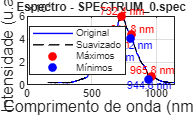


=== A processar: SPECTRUM_1.spec ===


Máximos:


  364.03 nm	3521.6
  410.15 nm	6773.2
  483.72 nm	17598.2
  558.86 nm	58714.4
  685.61 nm	57629.0
  860.25 nm	14892.2
  963.86 nm	4836.0


Mínimos:


  379.63 nm	2464.4
  432.20 nm	2922.4
  508.42 nm	7208.4
  615.84 nm	11000.6
  795.00 nm	9062.6
  944.08 nm	3619.8


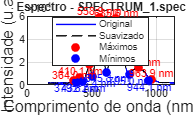


=== A processar: SPECTRUM_2.spec ===


Máximos:


  418.80 nm	8233.2
  573.62 nm	56982.0
  708.41 nm	60882.8
  813.90 nm	32165.4
  965.80 nm	6839.4


Mínimos:


  439.63 nm	6901.0
  633.21 nm	34547.4
  798.74 nm	29932.8
  942.60 nm	4774.6


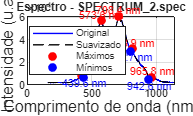


=== A processar: SPECTRUM_3.spec ===


Máximos:


  557.12 nm	55781.8
  708.69 nm	63966.8
  812.04 nm	40561.8
  965.56 nm	7111.8


Mínimos:


  605.83 nm	42388.8
  798.21 nm	36513.4
  944.08 nm	4946.6


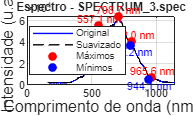


=== A processar: SPECTRUM_4.spec ===


Máximos:


  412.53 nm	6910.2
  485.78 nm	20506.8
  570.73 nm	58405.2
  703.15 nm	58950.6
  815.75 nm	16873.2
  965.07 nm	5412.6


Mínimos:


  438.44 nm	3816.4
  511.64 nm	12029.8
  625.53 nm	18520.4
  796.87 nm	14550.0
  943.83 nm	3911.2


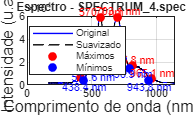


=== A processar: SPECTRUM_5.spec ===


Máximos:


  414.62 nm	5429.4
  491.38 nm	16897.6
  573.91 nm	45653.4
  706.75 nm	46651.2
  814.43 nm	14809.6
  964.59 nm	4773.4


Mínimos:


  435.76 nm	3976.2
  511.93 nm	12845.4
  630.65 nm	17737.2
  798.74 nm	13476.4
  943.34 nm	3498.2


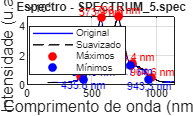

% ============================================================
% LEITURA DE VÁRIOS FICHEIROS .SPEC E DETEÇÃO DE MÁXIMOS E MÍNIMOS
% ============================================================

clear; clc; close all;

%% === 1. Selecionar a pasta com os ficheiros ===
pasta = uigetdir('C:\Users\joaod\OneDrive\Ambiente de Trabalho\picos maximo\spectrum', ...
                 'Seleciona a pasta com os ficheiros .spec');
if pasta == 0
    error('Nenhuma pasta selecionada.');
end

ficheiros = dir(fullfile(pasta, '*.spec'));
if isempty(ficheiros)
    error('Nenhum ficheiro .spec encontrado na pasta selecionada.');
end

%% === 2. Parâmetros ===
numHeaderLines = 13;          % número de linhas de cabeçalho antes dos dados
janelaSuavizacao = 5;         % tamanho da média móvel
minProminence = 1E3;          % sensibilidade da deteção de picos

% Tabela final com todos os ficheiros
resultados_totais = table();

%% === 3. Loop pelos ficheiros ===
for k = 1:length(ficheiros)
    ficheiro = fullfile(pasta, ficheiros(k).name);
    fprintf('\n=== A processar: %s ===\n', ficheiros(k).name);

    %% --- Ler ficheiro manualmente ---
    fid = fopen(ficheiro, 'r');
    if fid == -1
        warning('Não foi possível abrir o ficheiro: %s', ficheiro);
        continue;
    end
    linhas = textscan(fid, '%s', 'Delimiter', '\n', 'Whitespace', '');
    fclose(fid);
    linhas = linhas{1};

    % Encontrar início dos dados
    inicio = find(contains(linhas, 'Pixel'), 1, 'first');
    if isempty(inicio)
        warning('Formato inesperado em %s', ficheiro);
        continue;
    end

    % Extrair dados numéricos
    dados_linhas = linhas(inicio+1:end);
    dados = [];
    for i = 1:length(dados_linhas)
        linha = strtrim(dados_linhas{i});
        if isempty(linha), continue; end
        valores = str2double(strsplit(linha));
        if all(isfinite(valores)) && numel(valores) >= 3
            dados = [dados; valores(1:3)];
        end
    end
    if isempty(dados)
        warning('Nenhum dado numérico encontrado em %s', ficheiro);
        continue;
    end

    %% --- Extrair dados ---
    lambda = dados(:,2);
    intensidade = dados(:,3);

    %% --- Suavizar espectro ---
    intensidade_suave = smooth(intensidade, janelaSuavizacao);

    %% --- Deteção de MÁXIMOS ---
    [picos_max, locs_max] = findpeaks(intensidade_suave, lambda, ...
        'MinPeakProminence', minProminence);

    %% --- Deteção de MÍNIMOS ---
    [picos_min, locs_min] = findpeaks(-intensidade_suave, lambda, ...
        'MinPeakProminence', minProminence);
    picos_min = -picos_min; % inverter sinal de volta

    %% --- Mostrar resultados no terminal ---
    fprintf('Máximos:\n');
    for i = 1:length(picos_max)
        fprintf('  %.2f nm\t%.1f\n', locs_max(i), picos_max(i));
    end
    fprintf('Mínimos:\n');
    for i = 1:length(picos_min)
        fprintf('  %.2f nm\t%.1f\n', locs_min(i), picos_min(i));
    end

    %% --- Guardar resultados ---
    T_max = table(repmat(string(ficheiros(k).name), numel(picos_max), 1), ...
                  repmat("Máximo", numel(picos_max), 1), ...
                  locs_max(:), picos_max(:), ...
                  'VariableNames', {'Ficheiro','Tipo','Comprimento_onda_nm','Intensidade'});

    T_min = table(repmat(string(ficheiros(k).name), numel(picos_min), 1), ...
                  repmat("Mínimo", numel(picos_min), 1), ...
                  locs_min(:), picos_min(:), ...
                  'VariableNames', {'Ficheiro','Tipo','Comprimento_onda_nm','Intensidade'});

    resultados_totais = [resultados_totais; T_max; T_min];

    %% === NOVO BLOCO: Criar variável individual com os picos máximos ===
    nomeVar = matlab.lang.makeValidName(['picos_' erase(ficheiros(k).name, '.spec')]);
    assignin('base', nomeVar, table(locs_max(:), picos_max(:), ...
        'VariableNames', {'Comprimento_onda_nm','Intensidade'}));
    % -------------------------------------------------------------
    % Isto cria no workspace uma variável chamada por exemplo:
    %   picos_nomeDoFicheiro = [Comprimento_onda_nm | Intensidade]
    % -------------------------------------------------------------

    %% --- Gráfico individual ---
    figure('Color','w','Name', ficheiros(k).name);
    plot(lambda, intensidade, 'b-', 'LineWidth', 1); hold on;
    plot(lambda, intensidade_suave, 'k--', 'LineWidth', 1);
    plot(locs_max, picos_max, 'ro', 'MarkerFaceColor', 'r');
    plot(locs_min, picos_min, 'bo', 'MarkerFaceColor', 'b');
    xlabel('Comprimento de onda (nm)', 'FontSize', 12);
    ylabel('Intensidade (u.a.)', 'FontSize', 12);
    title(sprintf('Espectro - %s', ficheiros(k).name), 'Interpreter', 'none');
    grid on;
    legend('Original', 'Suavizado', 'Máximos', 'Mínimos', 'Location', 'best');

    % Anotar picos
    for i = 1:length(picos_max)
        text(locs_max(i), picos_max(i), sprintf('%.1f nm', locs_max(i)), ...
            'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center', ...
            'FontSize', 8, 'Color', 'r');
    end
    for i = 1:length(picos_min)
        text(locs_min(i), picos_min(i), sprintf('%.1f nm', locs_min(i)), ...
            'VerticalAlignment', 'top', 'HorizontalAlignment', 'center', ...
            'FontSize', 8, 'Color', 'b');
    end
end


%% === 4. Guardar resultados em ficheiro ===
if ~isempty(resultados_totais)
    outFile = fullfile(pasta, 'picos_maximos_minimos.csv');
    writetable(resultados_totais, outFile);
    fprintf('\n✅ Resultados (máximos e mínimos) guardados em:\n%s\n', outFile);
end


✅ Resultados (máximos e mínimos) guardados em:
C:\Users\joaod\OneDrive\Ambiente de Trabalho\Pastas\3ºano\picos maximo\spectrum\picos_maximos_minimos.csv
